# Rounding errors in the Vancouver Stock Exchange

In 1982, the Vancouver Stock Exchange started keeping a running index of all 1400 stocks in the exchange.  Every time a stock price changed, which happened about 2800 times a day, the index was updated and truncated to 3 decimal digits (approximately 10 binary digits: 2^10 = 1024).  The stock index was initialized to 1000.  Instead of recomputing each time, the index y was updated by adding the price difference `dx` divided by 1400.  After two years, the index was 480 points off.

Put the random number generator in its default state for reproducible results.

rng('default')

Average number of price changes per day.

n = 2800;

Random price changes

dx = 10*randn(n,1);

Coefficient `a` is the  the inverse of the number of stocks.

a = 1/1400;

Compute the stock index `y` as a running average by updating the stock index instead of averaging all the stock prices after every change in price.

Create a types table from MATLAB struct `T`.

clear T

Convergent rounding is unbiased.  Ten binary digits (approximately 3 decimal digits) is sufficient accuracy if the rounding is unbiased.

T.y = fi([],1,32,10,'RoundingMethod','Convergent');

Floor rounding causes the drift.  Uncomment the following line to see the adverse effect of truncating the result in the 1982 stock index.

%T.y = fi([],1,32,10,'RoundingMethod','Floor');

Cange the prototype to double by uncommenting the following line to return to the original floating-point types.

%T.y = []; % To get back to double

The following is the datatype-agnostic version of the algorithm.  Only the stock index `y` was quantized in the 1982 Vancouver Stock Exchange.  The number of stocks is an integer and the change in stock price is exact, so we leave this example with variables `a` and `dx` left in their original types.  The next chapters discuss in detail how to convert algorithms to all fixed point.

y = zeros(n,1, 'like',T.y);
y(1) = 1000;
for k = 2:n
    y(k) = y(k-1) + a * dx(k);
end

Plot results

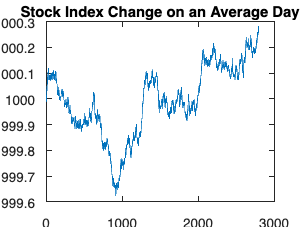

plot(y)
set(gca,'FontSize',18)
title('Stock Index Change on an Average Day')